# Controller Design Project - System Identification

## Yashar Zafari - 99106209

## Erfan Radfar -

## TF Model:

First we use IDDATA Sink Block in the Simulink to simply create iddata needed for estimating the transfer function.

load('rawdata.mat')
Gest=tfest(rawdata,2,0,NaN)

Gest =
 
  From input "u1" to output "y1":
            0.335
  --------------------------
  s^2 + 0.2381 s + 9.649e-07
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "rawdata".
Fit to estimation data: 100%                        
FPE: 5.925e-11, MSE: 5.866e-11                      


## Model Validation:

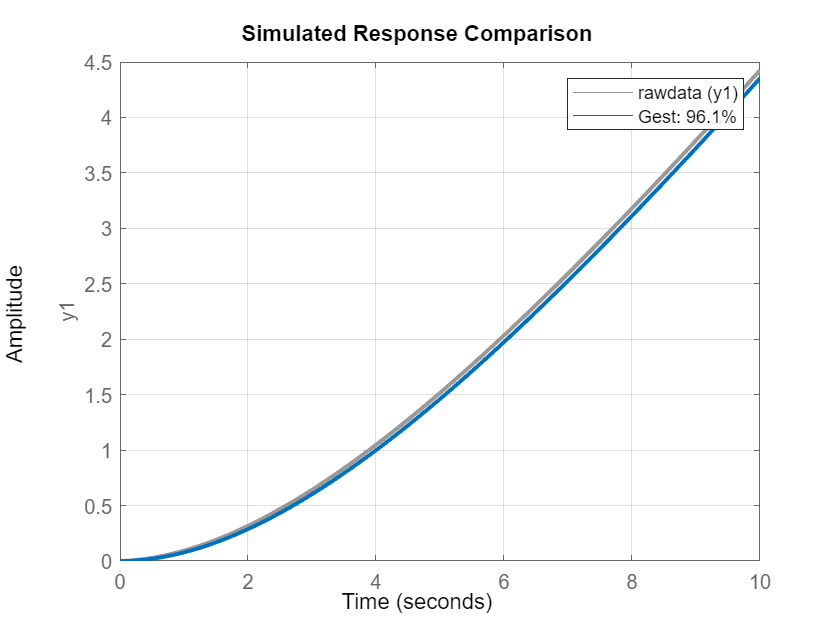

opt = compareOptions('InitialCondition', 'z');
compare(rawdata, Gest, opt);
set(findall(gca, 'Type', 'Line'),'LineWidth',2);
grid on

## SS Model:

Gss = ssest(rawdata, 1:10);

Gests=tf(Gss)

Gests =
 
  From input "u1" to output "y1":
      0.03613 s + 0.335
  --------------------------
  s^2 + 0.2381 s + 1.229e-15
 
Continuous-time transfer function.



## Model Validation:

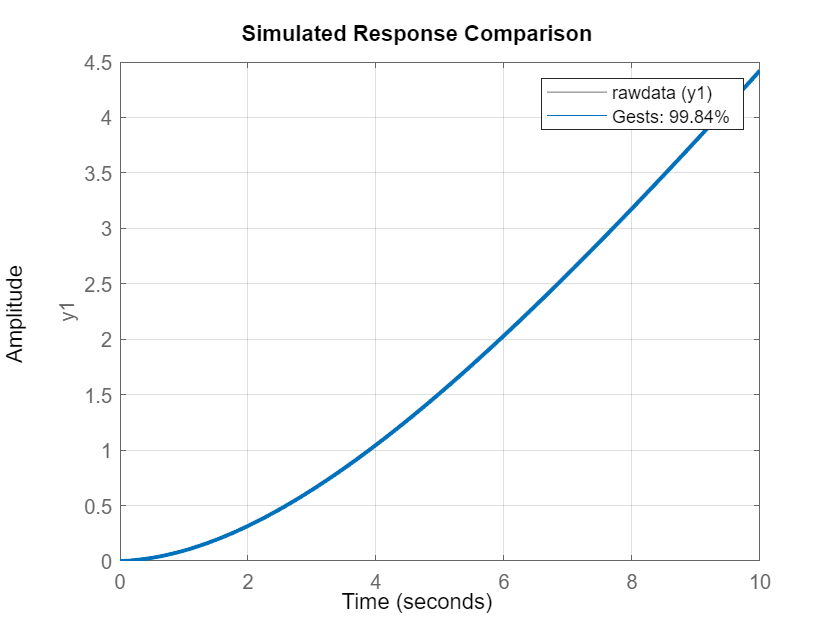

opt = compareOptions('InitialCondition', 'z');
compare(rawdata,Gests,opt);
set(findall(gca, 'Type', 'Line'),'LineWidth',2);
grid on